clear
clc

# **Conceptual UAV Design Constraints Calculator V1**

#### **By James Orendi**

#### **This calculator outputs the constraints graph & various other data, using the inputs provided**

#### **Assumption: UAV uses electrical powerplant, thus no mass change due to fuel depletion**

#### Remember, these values are theoretical ideals, actual aircraft will have lower efficiencies and values

#### For BMFA Weight Challenge Aircraft, it is expected that the Takeoff and Climb constraints are the major design constraints

## **Inputs**

**Constants**

g = 9.81 ; % m s^-2, Acceleration due to gravity
R = 287.1 ; % J kg^-1 K^-1, Specific Gas Constant
gamma = 1.4 ; % N/A, Specific Heat Ratio of a diatomic gas

#### Mass Design Values

We_A = 0.95 ; % <----- We_A and We_exp are not used, as the individual part
We_exp = -0.09 ; % <----- ^^^masses are used/approximated from similar sized aircraft instead

LDmax = 17.5 ; % This is a prop aircraft, so LDloiter is LDmax
LDloiter = LDmax % FOR PROPELLER AIRCRAFT

LDloiter = 17.5000

LDcruise = 0.866*LDmax

LDcruise = 15.1550

**Mission Altitudes and related values**

Cruise_alt = 35 ; % m
Takeoff_alt = 20 ; % m
Landing_alt = 20 ; % m
Cruise_speed_aircraft = 12 ; % m/s 

#### Function Call

originaldirectory = cd ;

cd([originaldirectory, '\Functions'])
[~,~,Cruise_air_density,Cruise_speed_of_sound] = GetAtmosProps(Cruise_alt,0,0)

Cruise_air_density = 1.2209

Cruise_speed_of_sound = 340.1596

[~,~,Takeoff_air_density,Takeoff_speed_of_sound] = GetAtmosProps(Takeoff_alt,0,0)

Takeoff_air_density = 1.2226

Takeoff_speed_of_sound = 340.2172

[~,~,Landing_air_density,Landing_speed_of_sound] = GetAtmosProps(Landing_alt,0,0)

Landing_air_density = 1.2226

Landing_speed_of_sound = 340.2172

cd(originaldirectory)

#### Cruise Speeds

Cruise_mach_number = Cruise_speed_aircraft/Cruise_speed_of_sound

Cruise_mach_number = 0.0353

Loiter_speed_aircraft = 0.76*Cruise_speed_aircraft

Loiter_speed_aircraft = 9.1200

## **Mass Breakdown & Payload Range**

**Battery Details**

Mass_battery = 170/1000 ; % kg
Charge_battery= 2200/1000 ; % Ah
Charge_battery_BASE_SI = Charge_battery*3600 ; % C
Voltage_battery = 11.1 ; % V, 3s
Energy_density_battery = Charge_battery_BASE_SI*Voltage_battery % J

Energy_density_battery = 8.7912e+04

**Expected Part Masses**

Mass_motor = 179/1000 ; % kg
Mass_ESC = 65/1000 ; % kg
Mass_servos = (8*4)/1000 ; % kg, 2 aileron, 1 elevator, 1 rudder
Mass_receiver = 7/1000 ; % kg
Mass_structure = 417/1000 ; % kg <--- THIS IS ENTIRELY ESTIMATED FOR THE STRUCTURE, PLEASE REVISE WITH BETTER VALUES IF/WHEN POSSIBLE
Mass_empty = Mass_motor+Mass_ESC+Mass_servos+Mass_receiver+Mass_structure % kg

Mass_empty = 0.7000

%Mass_empty = 750/1000 ; % kg

**Mass Breakdown Details**

Mass_payload = 4 ; % kg, Maximum mass of payload carried by aircraft

Mass_MTOW = Mass_battery + Mass_empty + Mass_payload % kg, Maximum Takeoff weight (mass) of aircraft

Mass_MTOW = 4.8700

Mass_fraction_battery = Mass_battery/Mass_MTOW % N/A, Fraction of MTOW weight comprised of fuel (battery)

Mass_fraction_battery = 0.0349

**Electric Aircraft Range Equation**

E_star = Charge_battery*Voltage_battery/Mass_battery % Wh/kg, Battery Energy Density

E_star = 143.6471


n_tot = 0.65 ; % N/A, Total mechanical efficiency, comprised of batteries, motor, and propeller efficiencies
Range = (Charge_battery_BASE_SI*Voltage_battery/Mass_MTOW)*n_tot*(1/g)*(LDcruise); % m, Max range of aircraft
t = (Charge_battery_BASE_SI*Voltage_battery/Mass_MTOW)*n_tot*(1/g)*(LDloiter)*(1/Loiter_speed_aircraft); % s, Max loiter time of aircraft

disp(['Max range of UAV is ',num2str(Range/1000),' km (estimated)'])

Max range of UAV is 18.1267 km (estimated)


disp(['Max loiter time of UAV is ',num2str(t/60),' min (estimated)'])

Max loiter time of UAV is 38.2521 min (estimated)


**Drag & Lift (Prospected) Values**

AR = 9.834 ; % Aspect Ratio
e = 0.75 ; % Oswald Efficiency Factor
CD0 = 0.017 ; % Zero-lift Drag Coefficient
Estimated_LD = 0.5*sqrt((pi*e*AR)/(CD0))

Estimated_LD = 18.4593

Clto = 1.65 ; % Coefficient of Lift upon Takeoff
Cll = 1.65 ; % Coefficient of Lift upon Landing

**Motor (Predicted) Values**

Thrust_motor_predicted = 3.2*9.81 % N

Thrust_motor_predicted = 31.3920

Thrust_weight_ratio_predicted = (Mass_MTOW*9.81)/Thrust_motor_predicted

Thrust_weight_ratio_predicted = 1.5219

## **Constraints**

**Required Graphing Variables**

WS_given = linspace(0,500,10001) ; % N/m^2 <--- A given range of Wing Loading values for use in calculations and Graphing

**Cruise Constraint**

qc_cruise = 0.5*Cruise_air_density*(Cruise_mach_number*Cruise_speed_of_sound)^2 % Dynamic pressure at Cruise

qc_cruise = 87.9040

K = 1/(pi*e*AR) % N/A, Drag Polar

K = 0.0432

TW_cruise = ((CD0.*qc_cruise./(WS_given))+ (K./qc_cruise).*WS_given) ;

**Take off Constraint**

Takeoff_distance = 26 ; % m
TW_takeoff = (1/(Clto*Takeoff_air_density*g*Takeoff_distance))*WS_given ;

**Climb Constraint**

Degrees_climb_angle = 6 ; % Deg
Radians_climb_angle = deg2rad(Degrees_climb_angle) ; % Climb angle is usually referred to using the symbol gamma (NOT SPECIFIC HEAT RATIO)
TW_climb = Radians_climb_angle+(1/LDloiter) ; % <------- This aircraft only has one engine, thus the LD for loitering is used instead! (otherwise one engine out LD is lower!)

**Landing Constraint**

Landing_distance = 30 ; % m
mu = 0.6 % Braking Friction Coefficient

mu = 0.6000

WS_landing = (0.6*(Landing_distance)*mu*g*Landing_air_density*Cll)/(1.2^2) % N/m^2

WS_landing = 148.4281

**Proposed Aircraft Values**

TW_Point = 0.295 ;
WS_Point = 145 ; % N/m^2, Alternatively Pa
disp(['WING LOADING = ',num2str(WS_Point),' N/m^2'])

WING LOADING = 145 N/m^2


disp(['THRUST TO WEIGHT RATIO = ',num2str(TW_Point)])

THRUST TO WEIGHT RATIO = 0.295


**Graph Data**

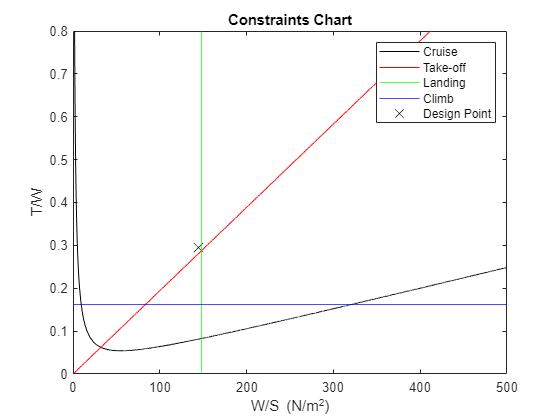

figure
plot(WS_given,TW_cruise,'k-')
hold on
plot(WS_given,TW_takeoff,'r-')
xline(WS_landing, 'g-')
yline(TW_climb,'b-')
plot(WS_Point,TW_Point,'x','Color','k','MarkerSize',10)
set(gca,'xlim',[0 500],'ylim',[0 0.8])
title('Constraints Chart')
xlabel('W/S (N/m^2)')
ylabel('T/W')
legend('Cruise','Take-off','Landing','Climb','Design Point')

**Additional Data**

wing_area = (Mass_MTOW*g)/(WS_Point) % m^2

wing_area = 0.3295

wing_span = sqrt(AR*wing_area) % m

wing_span = 1.8000